# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 201510607**

**학번**** : 강동헌**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/kangdongheon96/DSP.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

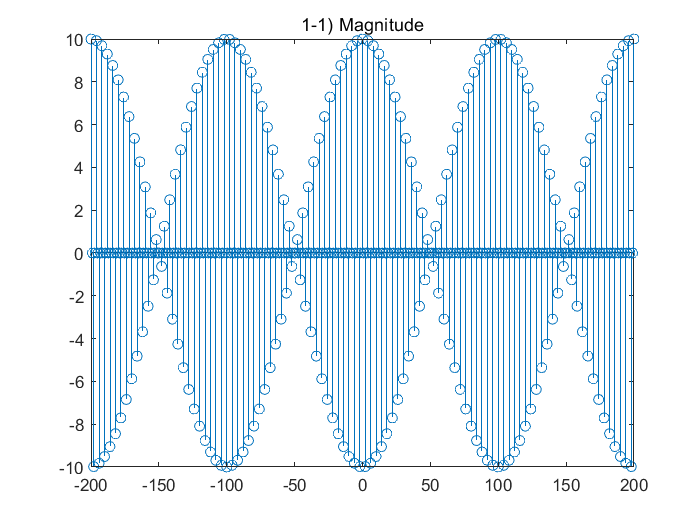

n = [-200:200]; 
x = 5*(cos(0.49*pi*n)+cos(0.51*pi*n));


 subplot(1,1,1); stem(n,x); title('1-1) Magnitude');

2) 

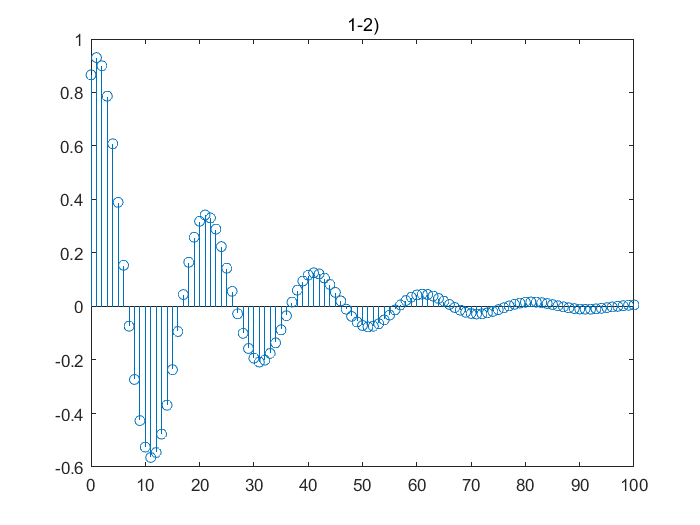

n = 0:100;
x = exp(-0.05*n).*sin(0.1*pi*n + pi/3);

subplot(1,1,1);  stem(n,x); title('1-2)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

n = 0:100; 
b = [1 2 0 1]; a = [1, -0.5, 0.25];
h= impz(b,a,n);
subplot(2,1,1);  stem(n,h); 
title('2-1)'); 
xlabel('n'); ylabel('h(n)');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

magH = abs(h);
sumH = sum(magH)

sumH = 5.8571

% sumH : finite -> stability 

3) 만약 이 시스템의 입력이 x(n) = [5 + 3 cos(0.2πn) + 4 sin(0.6πn)] u(n) 이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

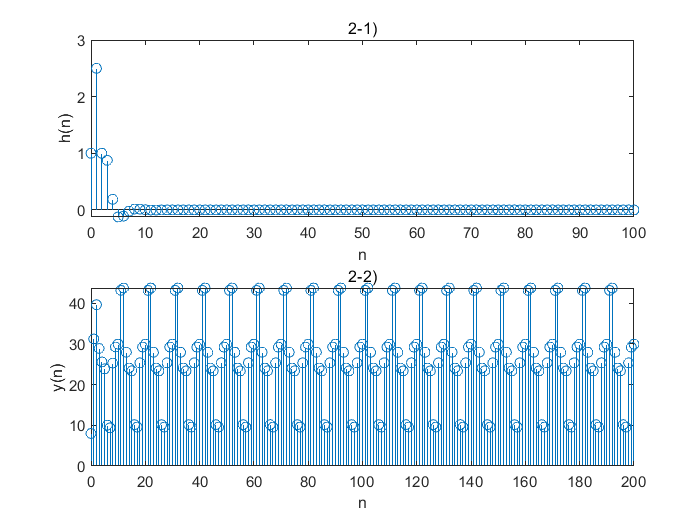

n = 0:200; 
b = [1 2 0 1]; a = [1 -0.5 0.25];
x =  5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n);
y = filter(b,a,x);

subplot(2,1,2);  stem(n,y);
title('2-2)'); 
xlabel('n'); 
ylabel('y(n)');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

% y(n) = h(n)*x(n) = (0.8^n)*Σ((-0.9/0.8)^k))

n = 0:50;
k= 0:n;
x = 0.8.^n; 
h = (-0.9).^n;
y = (0.8.^n)*sum((-0.9/0.8).^k).*ones(size(n)); 

subplot(1,3,1); stem(n,y); 
title('3-1');
xlabel('n'); ylabel('y(n)');


2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n2 = 0:25;
x2 = 0.8.^n2; 
h2 = (-0.9).^n2;
y2 = conv(h2,x2);

subplot(1,3,2);  stem(n,y2);
title('3-2');
xlabel('n'); ylabel('y(n)');




3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

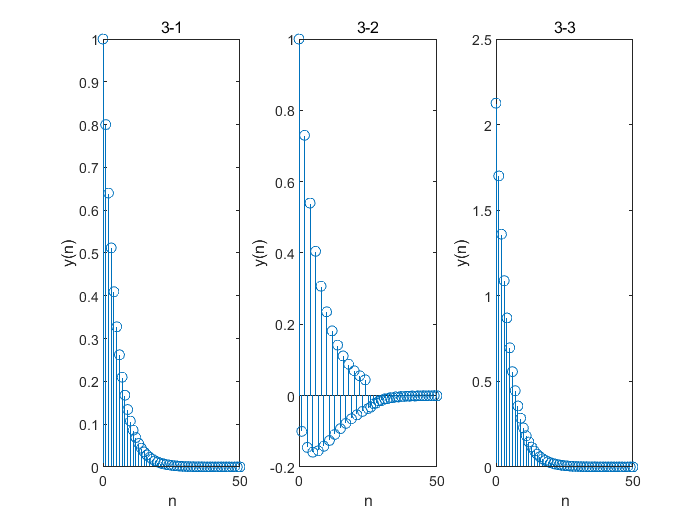

% x(n) * h(n) = y(n) =  (0.8^n)*Σ((-0.9/0.8)^k)) / 1/1-r
% b - 분모 a : 분자
b = [1+(0.9/0.8)];
a = [1];
y3 = filter(b,a,x);
subplot(1,3,3); stem(n,y3);

title('3-3');
xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

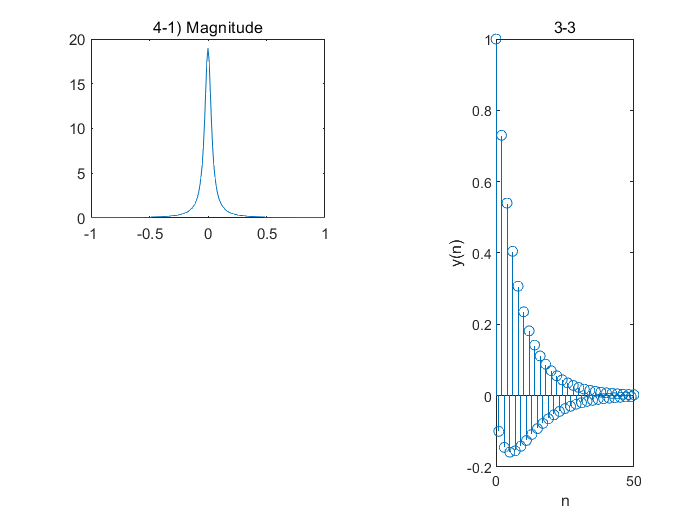

% h = (0.9)^|n|;

n = -100:100;  
N = abs(n);
h = (0.9).^N;

k = -100:100; 
w = (pi/100)*k; 

H = h*(exp(-j*pi/100)).^(n'*k); 


magH = abs(H);
angH = angle(H);


subplot(2,2,1);
plot(w/pi,magH); title('4-1) Magnitude');

subplot(2,2,2);
plot(w/pi,angH); title('4-1) Angle');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

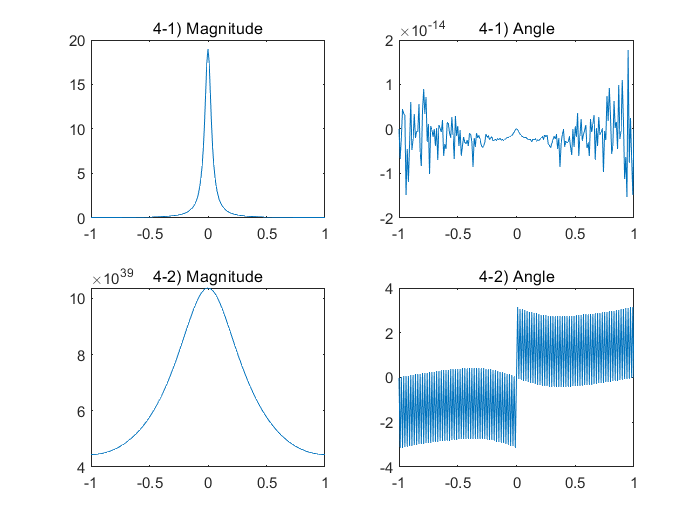


n2 = -100:100;  

h2 = ((0.5).^n2+(0.4).^n2);

k2 = -100:100; 
w2 = (pi/100)*k2; 

H2 = h2*(exp(-j*pi/100)).^(n2'*k2); 


magH2 = abs(H2);
angH2 = angle(H2);


subplot(2,2,3);
plot(w/pi,magH2); title('4-2) Magnitude');
subplot(2,2,4);
plot(w/pi,angH2); title('4-2) Angle');

5. (P3.17) 

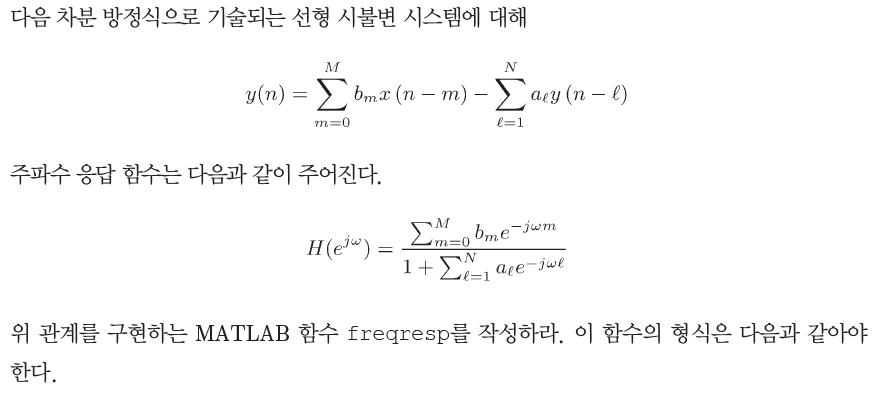

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$  

% y(n) - 0.95y(n-1) + 0.9025y(n-2) = x(n) - x(n-2)
k = -200:200;
w = (pi/200)*k;
a = [ 1.0000 -0.9500 0.9025];
b = [ 1.0000 0.0000 -1.0000]; 

[H] = freqresp(b,a,w);
magH = abs(H);
angH = angle(H);
subplot(2,2,1);
plot(w/pi,magH); title('4-1) Magnitude');
subplot(2,2,2);
plot(w/pi,angH); title('4-1) Angle');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

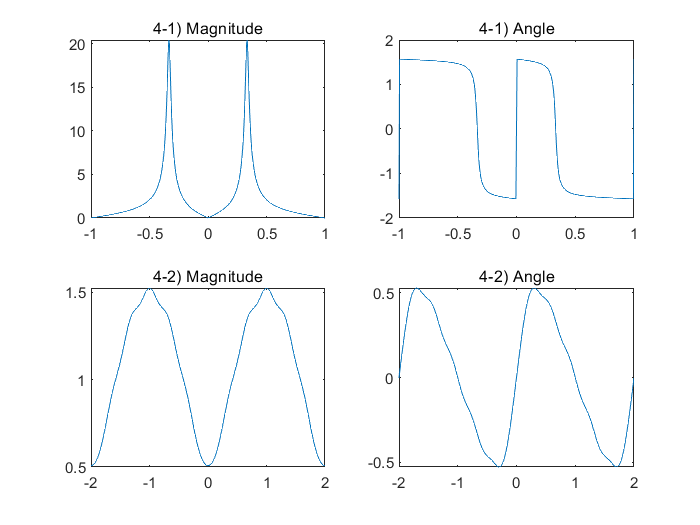

k = -200:200;
w = (pi/100)*k;
l = 0:5;
a = [ 0.5.^l];
b= [1];

H = freqresp(b,a,w);
magH = abs(H);
angH = angle(H);
subplot(2,2,3);
plot(w/pi,magH); title('4-2) Magnitude');
subplot(2,2,4);
plot(w/pi,angH); title('4-2) Angle');

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

% H = w 주파수에서 평가된 주파수 응답 어레이
% b = 분자 계수 배열
% a = 분모 계수 배열(a(1) = 1)
% w = 주파수 위치 배열
b = b;
a = a;
w = w;
m =  0:length(b)-1;
l = 0:length(a)-1;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
H = num./den;
end 